# Plotte Ergebnisse

## Import

data1=importdata('../cmake-build-debug/compareRNGs_interact1.tsv','\t',1);
data2=importdata('../cmake-build-debug/compareRNGs_endless1.tsv','\t',1);
data3=importdata('../cmake-build-debug/compareRNGs_endless2.tsv','\t',1);


## Transformiere endless-files

1E7

data3_E7=ones(length(1:10:size(data3.data,1))-1,3);
data3_E7(:,1)=ones(size(data3_E7,1),1)*1E7;
for i=1:size(data3_E7,1)
    j=(i-1)*10+1;
    data3_E7(i,2)=mean(data3.data(j:j+10,2));
    data3_E7(i,3)=mean(data3.data(j:j+10,4));
end

%data3_E8
data3_E8=ones(length(1:10:size(data3_E7,1))-11,3);
data3_E8(:,1)=ones(size(data3_E8,1),1)*1E8;
for i=11:size(data3_E8,1)
    j=(i-1)*10+1;
    data3_E8(i-10,2)=mean(data3_E7(j:j+10,2));
    data3_E8(i-10,3)=mean(data3_E7(j:j+10,3));
end

%data3_E9
data3_E9=ones(length(1:10:size(data3_E8,1))-11,3);
data3_E9(:,1)=ones(size(data3_E9,1),1)*1E9;
for i=11:size(data3_E9,1)
    j=(i-1)*10+1;
    data3_E9(i-10,2)=mean(data3_E8(j:j+10,2));
    data3_E9(i-10,3)=mean(data3_E8(j:j+10,3));
end

%data3_E10
data3_E10=ones(length(1:10:size(data3_E9,1))-11,3);
data3_E10(:,1)=ones(size(data3_E10,1),1)*1E10;
for i=11:size(data3_E10,1)
    j=(i-1)*10+1;
    data3_E10(i-10,2)=mean(data3_E9(j:j+10,2));
    data3_E10(i-10,3)=mean(data3_E9(j:j+10,3));
end
%data3_E11
data3_E11=ones(length(1:10:size(data3_E10,1))-11,3);
data3_E11(:,1)=ones(size(data3_E11,1),1)*1E10;
for i=11:size(data3_E11,1)
    j=(i-1)*10+1;
    data3_E11(i-10,2)=mean(data3_E10(j:j+10,2));
    data3_E11(i-10,3)=mean(data3_E10(j:j+10,3));
end

## Genauigkeit - Konvergenz

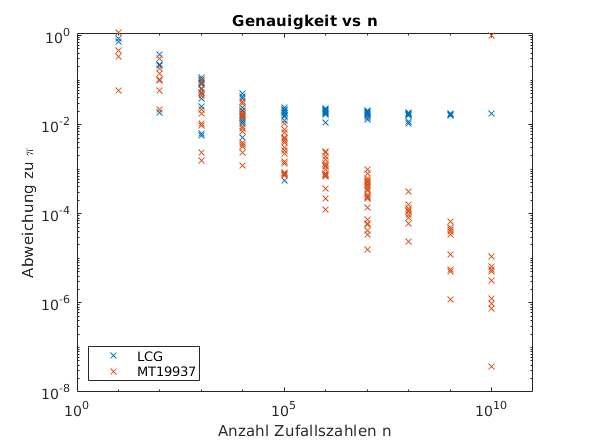

figure()
p1=loglog(data1.data(:,1),abs(data1.data(:,2)),'x');
hold on
p2=loglog(data1.data(:,1),abs(data1.data(:,4)),'x');
% 1E7
loglog(data3_E7(1:10,1),abs(data3_E7(1:10,2)),'x',"Color",p1.Color)
loglog(data3_E7(1:10,1),abs(data3_E7(1:10,3)),'x',"Color",p2.Color)
% 1E8
loglog(data3_E8(1:10,1),abs(data3_E8(1:10,2)),'x',"Color",p1.Color)
loglog(data3_E8(1:10,1),abs(data3_E8(1:10,3)),'x',"Color",p2.Color)
% 1E9
loglog(data3_E9(1:10,1),abs(data3_E9(1:10,2)),'x',"Color",p1.Color)
loglog(data3_E9(1:10,1),abs(data3_E9(1:10,3)),'x',"Color",p2.Color)
% 1E10
loglog(data3_E10(1:10,1),abs(data3_E10(1:10,2)),'x',"Color",p1.Color)
loglog(data3_E10(1:10,1),abs(data3_E10(1:10,3)),'x',"Color",p2.Color)
% 1E11
loglog(data3_E11(1:5,1),abs(data3_E11(1:5,2)),'x',"Color",p1.Color)
loglog(data3_E11(1:5,1),abs(data3_E11(1:5,3)),'x',"Color",p2.Color)

xlim([1 1E11])
title('Genauigkeit vs n')
xlabel('Anzahl Zufallszahlen n')
ylabel('Abweichung zu \pi')
legend('LCG','MT19937','Location',"southwest")

## Laufzeit

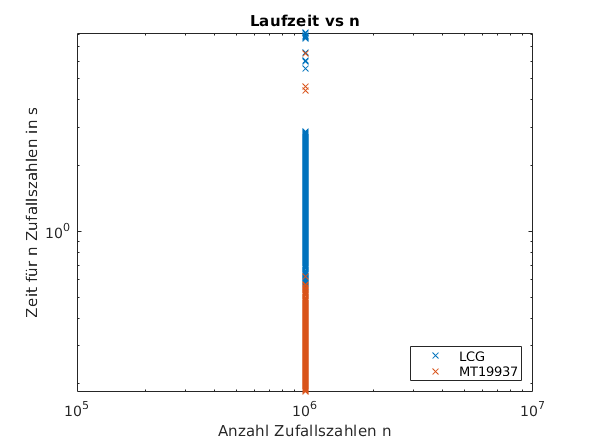

figure()
loglog(data3.data(:,1),data3.data(:,3)*1e-6,'x')
hold on
loglog(data3.data(:,1),data3.data(:,5)*1e-6,'x')
title('Laufzeit vs n')
xlabel('Anzahl Zufallszahlen n')
ylabel('Zeit für n Zufallszahlen in s')
legend('LCG','MT19937',"location",'southeast')

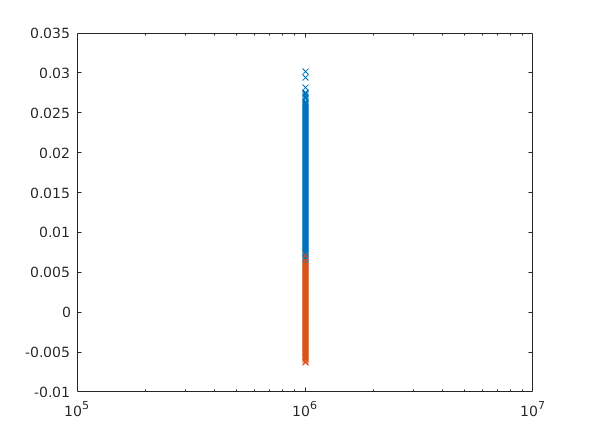

figure()
semilogx(data3.data(:,1),data3.data(:,2),'x')
hold on
semilogx(data3.data(:,1),data3.data(:,4),'x')

## Sonstige Kennzahlen

Abweichung_mittel=mean(data3.data(:,4)+pi)-pi

Abweichung_mittel = 4.0084e-06

Anzahl_an_Zeilen=length(data3.data(:,4))

Anzahl_an_Zeilen = 1638000